# Quantitative Methods for Finance

2025 Marina Dolfin

# QMF1_1_Data_Analysys

## Use of Import and Plot Tools

This activity introduces the basic workflow of MATLAB in a financial context. You will learn how to:

- Import financial data from Excel

- Plot stock prices over time

- Compute simple returns

- Visualize and save your results

Step 1: Collect the spreadsheet `Data.xlsx`** into the Current Folder**

**Instruction:**

Place the file `Data.xlsx` in your MATLAB Current Folder.

**Solution:**

Download the Excel file `Prices.xlsx` from the repository and save it into the Current Folder of MATLAB.

**Step 2 (option 1): Use the Import Tool to import the dataset as column vectors**

**Instruction:**

Import the entire dataset as column vectors.

**Solution:**

- Double-click the file in the Current Folder (or right-click → *Import Data*).

- In the Import Tool, set the output type to **Column Vectors**.

- Click **Import Selection**.

**Step 2 (option 2):**

% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 13);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A2:M166";

% Specify column names and types
opts.VariableNames = ["Date", "AAPL", "MSFT", "NVDA", "GOOGL", "GOOG", "JPM", "GS", "HSBC", "KO", "PG", "XOM", "SHEL"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
Data2 = readtable("C:\Users\mdolf\OneDrive\Documents\Didattica 2026\MATLAB\Codes\Data\Data.xlsx", opts, "UseExcel", false);

% Convert to output type
Date2 = Data2.Date;
AAPL2 = Data2.AAPL;
MSFT = Data2.MSFT;
NVDA = Data2.NVDA;
GOOGL = Data2.GOOGL;
GOOG = Data2.GOOG;
JPM = Data2.JPM;
GS = Data2.GS;
HSBC = Data2.HSBC;
KO = Data2.KO;
PG = Data2.PG;
XOM = Data2.XOM;
SHEL = Data2.SHEL;

% Clear temporary variables
clear Data2

**Step 3: Plot Apple prices against the dates**

**(Use the names of the variable that you imported; it depends if you used Step 2(option1) or Step 2(option2). In the example it has been applied Step 2 (option 2)**

**Instruction:**

Plot Apple stock prices against time.

**Solution:**

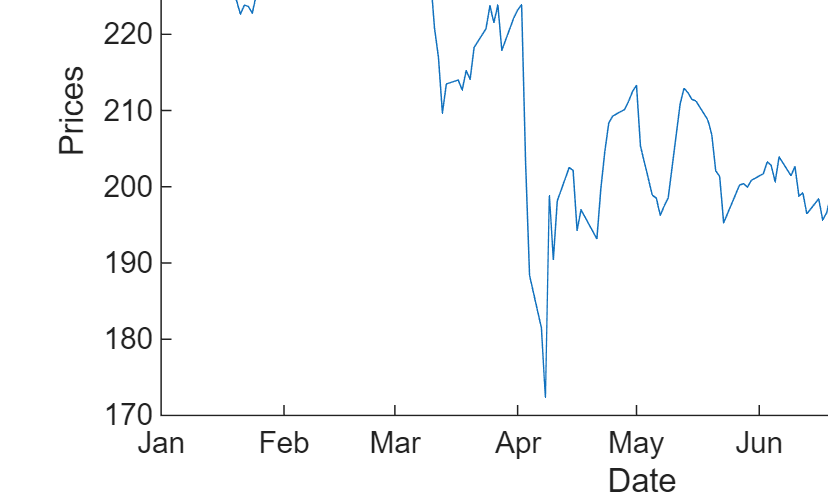

stock = AAPL2;

plot(Date2, stock)
xlabel('Date'); ylabel('Prices');
title('Price Time Series')

**Step 4: Compute Apple logarithmic returns**

**Instruction:**

Compute Apple logarithmic returns and store them in a variable `returns`.

**Solution:**

returns = tick2ret(stock)

returns =    -0.0020
    0.0067
   -0.0114
    0.0020
   -0.0241
   -0.0103
   -0.0048
    0.0197
   -0.0404
    0.0075
   -0.0319
    0.0053
   -0.0008
   -0.0039
    0.0318


**Step 5: Visualize both prices and returns**

**Instruction:**

Use subplots to display prices and returns in the same figure.

**Solution:**

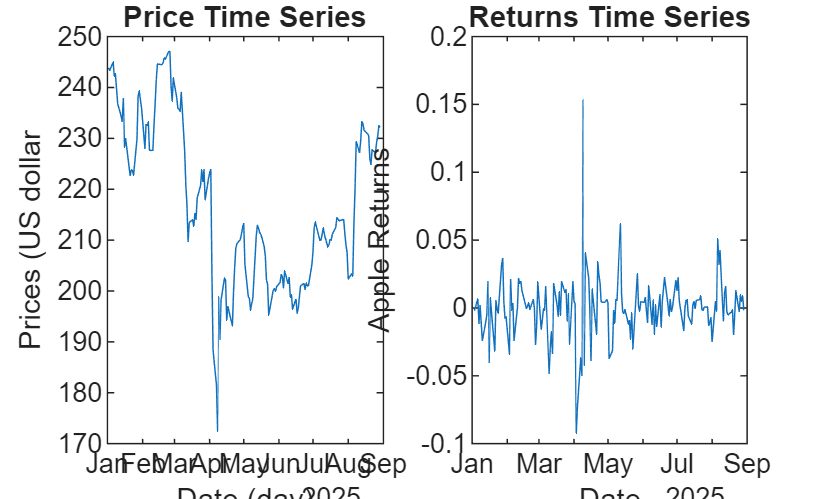

subplot(1,2,1)
plot(Date2, stock)
xlabel('Date (day)'); ylabel('Prices (US dollar');
title('Price Time Series')
subplot(1,2,2)
plot(Date2(2:end), returns)
xlabel('Date'); ylabel('Apple Returns');
title('Returns Time Series')

**Step 6: Save the figure**

**Instruction:**

Save the graph as a MATLAB figure named `exerciseI.fig`.

**Solution:**

In the figure window, go to **File → Save As** and save as `exerciseI.fig`.

**Completed!**

disp('Activity I Completed!')

Activity I Completed!
